# Mission-Creator

## Planificacion de la Ruta de Cobertura

Coberture Path Planning - Planificacion de la ruta de cobertura

Genera los transects y los grafica la region de interes (ROI)

Guarda los waypoints en el formato QGC WPL 110

Implementa una version minimalista del algoritmo implementado en QGC QGroundControl, en el archivo [SurveyComplexItem.cc](https://github.com/mavlink/qgroundcontrolsrc/MissionManager/SurveyComplexItem.cc)

## Inicializar

clear variables
clc
close all

## Datos de prueba para las coordenadas del polígono en LLA

lat = [-25.3253, -25.3256, -25.3257, -25.3254,-25.3253]';  % Latitudes de ejemplo
lon = [-57.6391, -57.6391, -57.6395, -57.6396,-57.6391]';  % Longitudes de ejemplo
alt = [3, 3, 3, 3, 3]';  % Altitud constante (en metros)

lla = [lat, lon, alt];
lla0  = [-25.3253 -57.6391 0];

latlimits = [-25.3257611 -25.3246139]; % ROI-01 y R0I-02
lonlimits = [-57.6396222 -57.6386111];
geocenter = [mean(latlimits) mean(lonlimits) 0];

## Convertir LLA a NED

%puntos = lla2ned(lla, lla0, 'flat');
puntos = lla2ned(lla, geocenter, 'flat');
x = puntos(:,1,:);
y = puntos(:,2,:);

% Crear polígono
polygonPoints = [x, y];
%plot_polygon(polygonPoints, 'Area de Cobertura');

## Llamar a la función generateTransects

Parámetros del algoritmo de generacion de Transectos

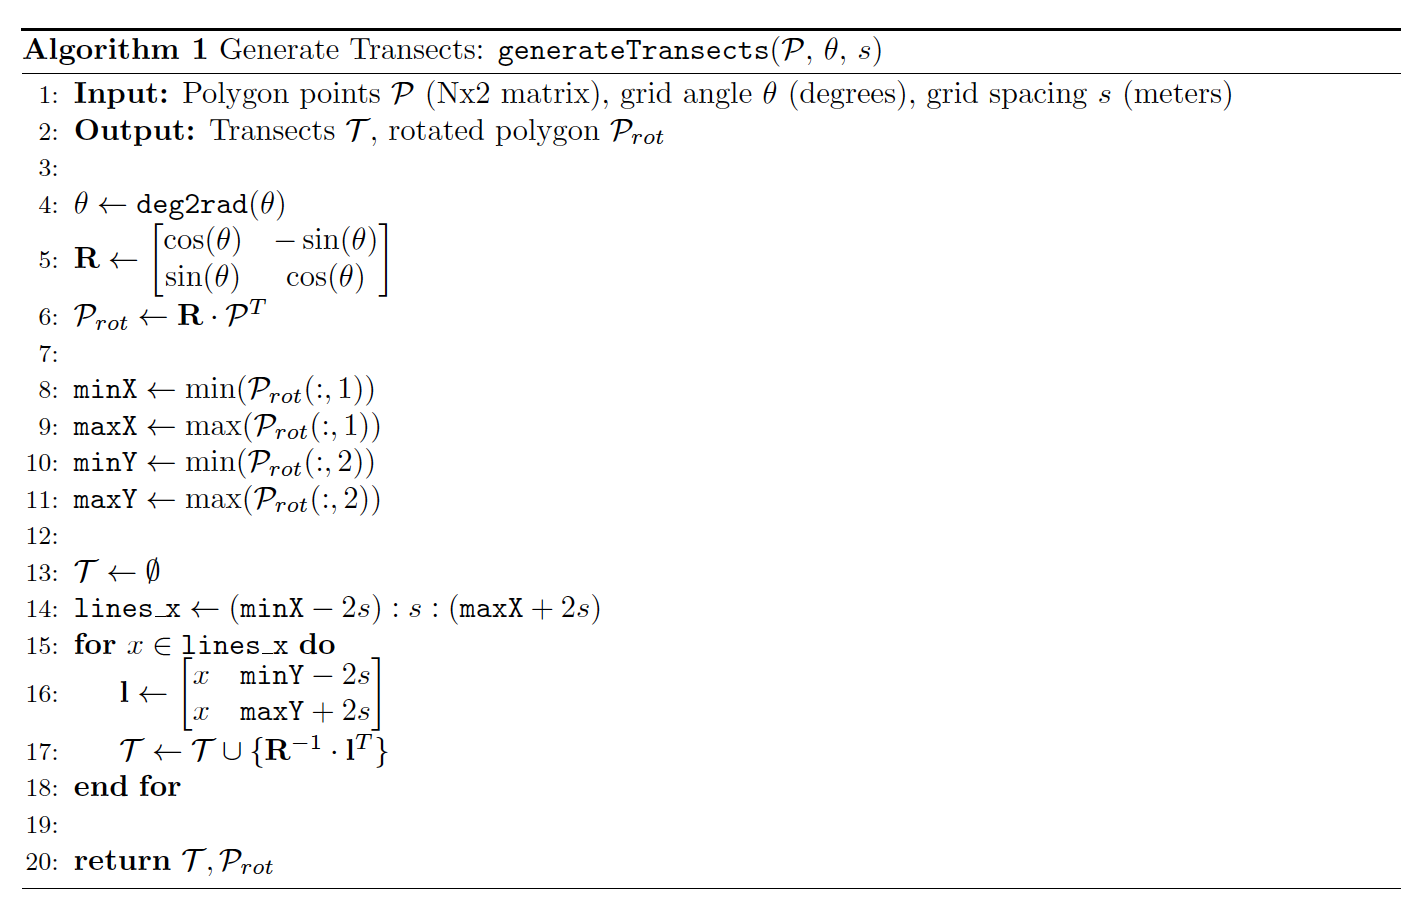

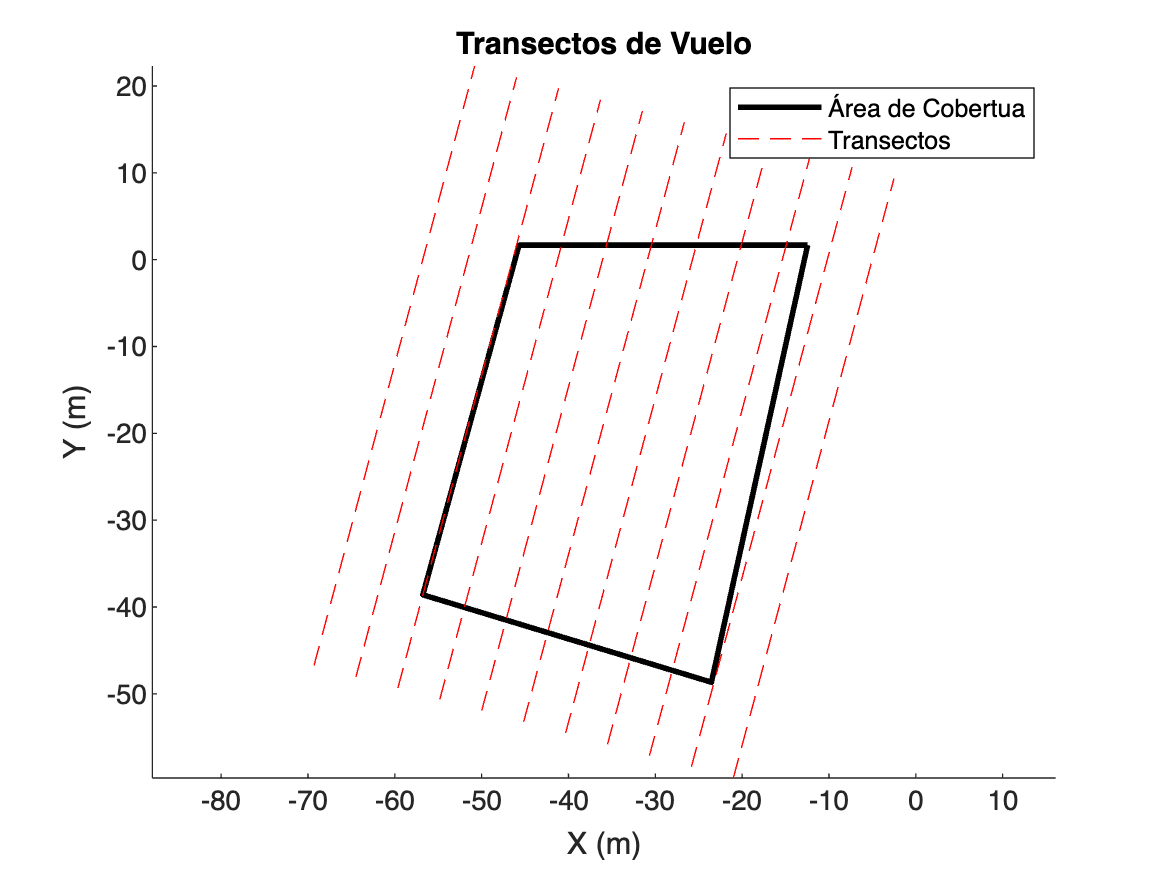


gridAngle = 15;  % Ángulo de la cuadrícula en grados
gridSpacing = 5;  % Espaciado de la cuadrícula en metros

[transects_ori, rotatedPolygon] = generateTransects(polygonPoints, gridAngle, gridSpacing);
plot_transects(polygonPoints,transects_ori)

## Obtener los transectos que intersectan el poligon

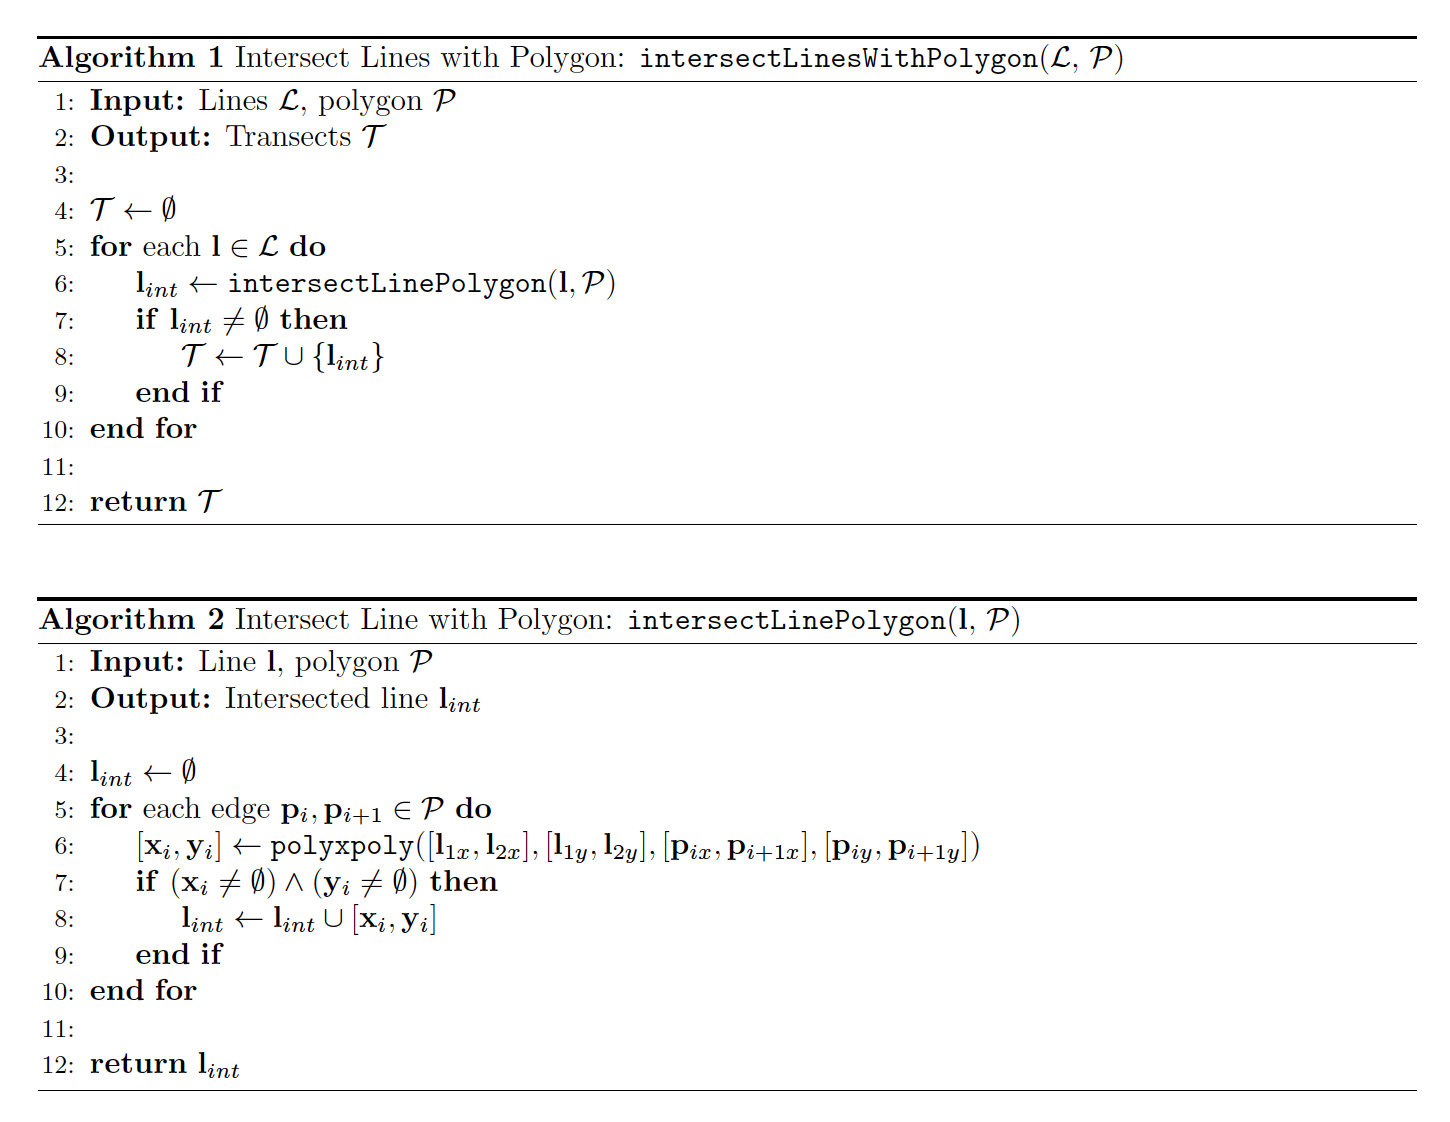

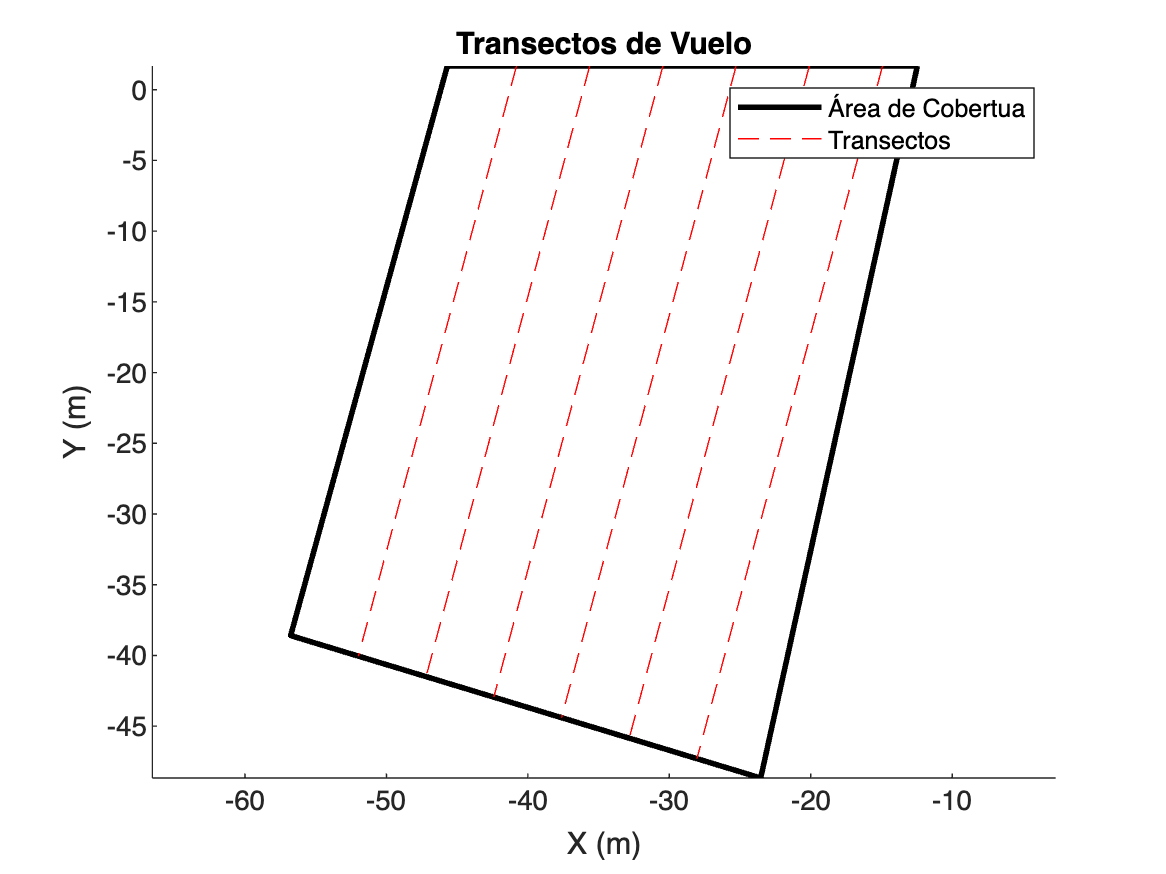

transects_ori = intersectLinesWithPolygon(transects_ori, polygonPoints);
plot_transects(polygonPoints,transects_ori)

### Revisar el contenido de los transects

transects_ori{1} = [[x1 y1];[x2,y2]]

wp_1_1 = [transects_ori{1}(1,:), mean(alt)];
wp_1_2 = [transects_ori{1}(2,:), mean(alt)];
wp_1_1_lla = ned2lla(wp_1_1, geocenter, "flat");
wp_1_2_lla = ned2lla(wp_1_1, geocenter, "flat");

### Convertir a LLA los trasects respetando el orden

Suponiendo que transects_ori es una celda de transectos y alt es un array de alturas

num_transects = length(transects_ori);
W01 = zeros(num_transects, 3); % Ajusta el tamaño según sea necesario
W01_label = [" W01"," W03"," W05"," W07"," W09", " W11"];
W02 = zeros(num_transects, 3); % Ajusta el tamaño según sea necesario
W02_label = [" W02"," W04"," W06"," W08"," W10", " W12"];

for i = 1:num_transects
    % Crear las nuevas variables para cada transecto
    wp_src = [transects_ori{i}(1,:), mean(alt)];
    wp_dst = [transects_ori{i}(2,:), mean(alt)];
    
    % Convertir a LLA
    wp_src_lla = ned2lla(wp_src, geocenter, 'flat');
    wp_dst_lla = ned2lla(wp_dst, geocenter, 'flat');
    
    % Almacenar los resultados en matrices manteniendo el orden
    W01(i, :) = wp_src_lla;
    W02(i, :) = wp_dst_lla; % Con W01 grafica bien!!
end

## Crear la secuencia de visita a los Waypoints  manualmente

Impares de W01: W01, W03, W05, W07, W09, W11 Pares de W02: W02, W04, W06, W08, W10, W12

wp_lla = [
    W01(1, :);  % W01
    W02(1, :);  % W02
    W02(2, :);  % W04
    W01(2, :);  % W03
    W01(3, :);  % W05
    W02(3, :);  % W06
    W02(4, :);  % W08
    W01(4, :);  % W07
    W01(5, :);  % W09
    W02(5, :);  % W10
    W02(6, :);  % W12
    W01(6, :)   % W11
];

### Verificar que los puntos esten dentro de la region de cobertura

Coordenadas de los waypoints

lat_wpq = wp_lla(:,1,:);
lon_wpq = wp_lla(:,2,:);

% Coordenadas de los puntos del polígono (lla)
lat_lla = lla(:, 1);
lon_lla = lla(:, 2);

% Verificar si los waypoints están dentro del polígono definido por lla
[in, on] = inpolygon(lat_wpq, lon_wpq, lat_lla, lon_lla);

% Los waypoints que están dentro del polígono o en el borde del polígono
waypoints_dentro = wp_lla(in | on, :);

% Imprimir los waypoints que están dentro del polígono
disp('Waypoints dentro del área definida por lla:');

Waypoints dentro del área definida por lla:


disp(waypoints_dentro);

  -25.3256  -57.6391   -3.0000
  -25.3257  -57.6395   -3.0000
  -25.3256  -57.6395   -3.0000
  -25.3255  -57.6391   -3.0000
  -25.3255  -57.6391   -3.0000
  -25.3256  -57.6395   -3.0000
  -25.3255  -57.6396   -3.0000
  -25.3254  -57.6391   -3.0000
  -25.3254  -57.6391   -3.0000
  -25.3255  -57.6396   -3.0000
  -25.3254  -57.6396   -3.0000
  -25.3253  -57.6391   -3.0000



size(waypoints_dentro)

ans =     12     3


## Graficar waypoints que forman parte del transect

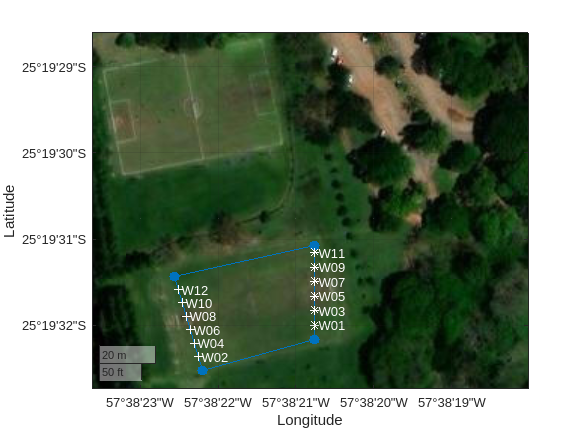

fig3 = figure();
gax3 = geoaxes(fig3);
% Si esto funciona, intenta agregar el basemap
set(gax3, 'Basemap', 'satellite');

% Graficar los puntos que definen la region de interes (ROI)
% geografico
geoplot(gax3,lla(:,1),lla(:,2),MarkerSize=25,Marker=".")
% Graficar los puntos que son los waypoints
hold on
geoplot(gax3,W01(:,1,:),W01(:,2,:),"w*")
text(gax3,W01(:,1,:),W01(:,2,:),W01_label,'Color','white')
geoplot(gax3,W02(:,1,:),W02(:,2,:),"w+")
text(gax3,W02(:,1,:),W02(:,2,:),W02_label,'Color','white')
geolimits(latlimits,lonlimits);

% Guardar la imagen
% exportgraphics(gcf, 'ROI.png', 'Resolution', 300);

## Graficar Transectos 

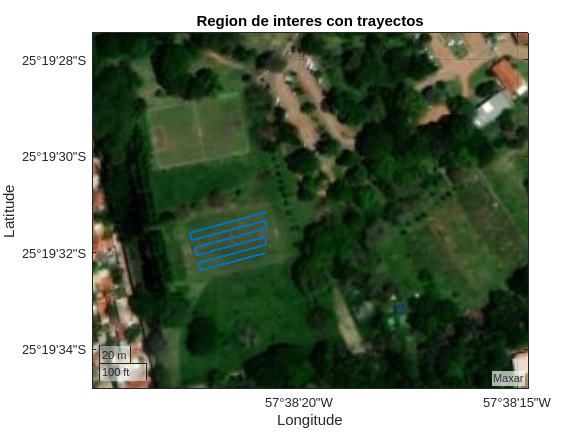

fig4 = figure();
gax4 = geoaxes(fig4);
set(gax4, 'Basemap', 'satellite');
% Graficar los waypoints que constituyen el path
hold on
% geoplot(gax4,W01(:,1,:),W01(:,2,:),"w*")
% text(gax4,W01(:,1,:),W01(:,2,:),W01_label,'Color','white')
% geoplot(gax4,W02(:,1,:),W02(:,2,:),"w+")
% text(gax4,W02(:,1,:),W02(:,2,:),W02_label,'Color','white')

geoplot(gax4,wp_lla(:,1,:),wp_lla(:,2,:),'LineWidth', 1.5);
geolimits(latlimits,lonlimits);

geolimits([-25.32634 -25.32429],[-57.64021 -57.63743])
title("Region de interes con trayectos")

% Guardar la imagen
%exportgraphics(gcf, 'Transectos.png', 'Resolution', 300);

## Graficar la Region de Interes y el PATH

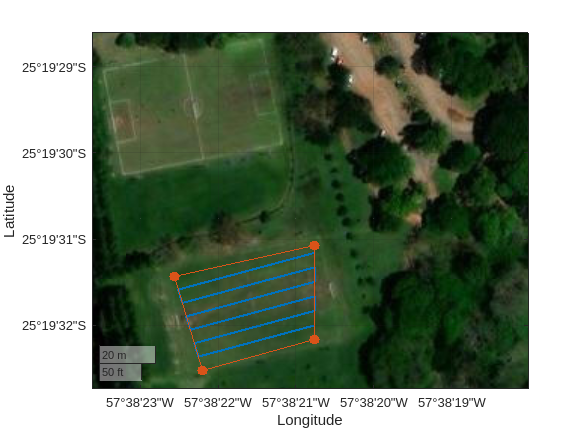

fig5 = figure();
gax5 = geoaxes(fig5);
set(gax5, 'Basemap', 'satellite');
% Graficar los waypoints que constituyen el path
hold on
% geoplot(gax5,W01(:,1,:),W01(:,2,:),"w*")
% text(gax5,W01(:,1,:),W01(:,2,:),W01_label,'Color','white')
% geoplot(gax5,W02(:,1,:),W02(:,2,:),"w+")
% text(gax5,W02(:,1,:),W02(:,2,:),W02_label,'Color','white')

geoplot(gax5,wp_lla(:,1,:),wp_lla(:,2,:),'LineWidth', 1.5);
geoplot(gax5,lla(:,1),lla(:,2),MarkerSize=25,Marker=".")
geolimits(latlimits,lonlimits);

% Guardar como imagen
%exportgraphics(gcf, 'roiTransects.png', 'Resolution', 300);

## Graficar PATH + TAKEOFF/LANDING 

VER ConfigurarRegionInteresFcn.m Datos obtenidos en sitio Coordenadas de aterrizaje

landLat = -25.3254889;
landLon = -57.6389917;
landAlt = 0;

% Coordenadas de despegue (takeoff)
 takeoffLat = -25.3253278;
 takeoffLon = -57.6389861;
 takeoffAlt = 0;
% 
% % Coordenadas geodesicas region de interes
% llapoints = [[-25.3257028 -57.6395167 0]; ...   % W01 - Waipoint 01
%             [-25.3254333 -57.6395861 0]; ...    % W02
%             [-25.3253556 -57.6391472 0]; ...    % W03
%             [-25.3256056  -57.6390583 0]; ...   % W04
%             [-25.3257028 -57.6395167 0]];       % W01

takeoff = [takeoffLat, takeoffLon,takeoffAlt];
% landing = [landLat, landLon,landAlt]; %
landing = takeoff; % Asumimos que misma posicion de despegue y aterrizaje

### Graficar ROI+PATH+TAKEOFF/LANDING

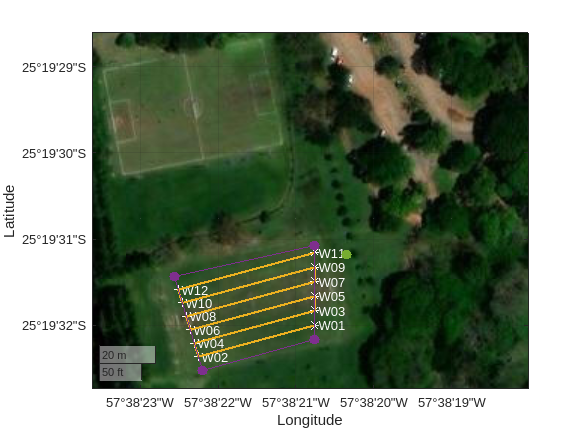

fig6 = figure();
gax6 = geoaxes(fig6);
set(gax6, 'Basemap', 'satellite');
% Graficar los waypoints que constituyen el path
hold on
geoplot(gax6,W01(:,1,:),W01(:,2,:),"w*")
text(gax6,W01(:,1,:),W01(:,2,:),W01_label,'Color','white')
geoplot(gax6,W02(:,1,:),W02(:,2,:),"w+")
text(gax6,W02(:,1,:),W02(:,2,:),W02_label,'Color','white')

geoplot(gax6,wp_lla(:,1,:),wp_lla(:,2,:),'LineWidth', 1.5);
geoplot(gax6,lla(:,1),lla(:,2),MarkerSize=25,Marker=".")
geoplot(gax6,takeoff(:,1),takeoff(:,2),MarkerSize=25,Marker=".")
geolimits(latlimits,lonlimits);

% Guardar como imagen
%exportgraphics(gcf, 'roiTransects.png', 'Resolution', 300);

### Exportar el PATH en formato compatible con QGC

Similar a la funcion exportWaypointsPlan(cp,solnInfo,"misionLED.waypoints")

`MAVLINK EXPORT FORMAT:`

`<INDEX> <CURRENT WP> <COORD FRAME> <COMMAND> <PARAM1> <PARAM2> <PARAM3> <PARAM4> <PARAM5/X/LATITUDE> <PARAM6/Y/LONGITUDE> <PARAM7/Z/ALTITUDE> <AUTOCONTINUE>`

[FileFormat](https://mavlink.io/en/file_formats/)

[MAV commanda messages](https://ardupilot.org/copter/docs/common-mavlink-mission-command-messages-mav_cmd.html#mav-cmd-nav-waypoint)

writeWaypointsToFile(wp_lla, 'misionLED.waypoints', takeoff, landing)

Proceso de escritura de waypoints en el archivo "misionLED.waypoints" finalizado con éxito.


readAndPrintWaypoints('misionLED.waypoints');

   Index      Command         Latitud        Longitud         Altitud
   -----      -------         -------        --------        --------
       0           22      -25.325328      -57.638986            0.00
       1           16      -25.325556      -57.639100           -3.00
       2           16      -25.325657      -57.639514           -3.00
       3           16      -25.325614      -57.639529           -3.00
       4           16      -25.325509      -57.639100           -3.00
       5           16      -25.325462      -57.639100           -3.00
       6           16      -25.325570      -57.639543           -3.00
       7           16      -25.325527      -57.639558           -3.00
       8           16      -25.325416      -57.639100           -3.00
       9           16      -25.325369      -57.639100           -3.00
      10           16      -25.325484      -57.639572           -3.00
      11           16      -25.325441      -57.639586           -3.00
      12           1